# Lab 3: Fourier Series and the Fourier Transform

## Section 1: Fourier Series

Recall from the notes that to fully classify any LTI system one needs to know the system's impulse response h(t). The frequency response of a system is H(w) defined as:


$$\[
H(\omega) = \int_{-\infty}^{\infty} h(\tau)\, e^{-j\omega \tau}\, d\tau
\]
$$


Notice how the integrand is a function of both time (tau) and frequency (omega), but we integrate wrt tau so we are left with a function of only frequency. H(w) is called the "frequecny response" of a system because it is the coefficent that pops up when you input a signal of pure frequency into the LTI system, see the notes for the full derivation:


$$\[
T (e^{j\omega t}) = H(\omega) e^{j\omega t}
\]
$$


This shows that the pure frequency input $x(t) = e^{j\omega t
$ is an *eigenfunction *of the LTI system T(.) with *eigenvalue* H(w). 

Any periodic signal x(t) may be represented as a weighted sum of sinusoidal signals with different frequencies. In fact, you often need every countable frequency to fully comprise the signal, written as:


$$\[
x(t) = \sum_{k=-\infty}^{\infty} c_k e^{j k \omega_0 t}
\]$$


Where x(t) has period T = 1/w0. Note that $\[
c_k \in \mathbb{C}
\]$. Note that most signals x(t) are real valued, but are still represented above as a weighted sum of complex exponentials. As x(t) is periodic with period t, x(t+T) = x(t).

Also recall that a frequency f and an angular frequency w are related by $\omega = 2\pi f = \frac{2\pi }{T}
$ and hence the above formula for x(t) is commonly written as:


$$\[
x(t) = \sum_{k=-\infty}^{\infty} a_k e^{j \left( \frac{2\pi k}{T} \right) t}
\$$


Even though we sum over the whole set of integers, many of these coeffiencients may be zero. 

### How to formulate x(t) from the Fourier Series formula?

The main problem with Fourier series formulation is defining the coefficients $a_k
$. Note that the exponential term is fully classified by eye, the only variable with a numerical value is T, which is just the period of the given input signal. 'k' ranges from negative infinity to infinity, t is a real variable and j is the square root of negative 1.

An important property of basis functions in general, and specifically complex exponentials that comprise our Fourier domain, is that they are orthogonal to each other. Recall for vectors this is with respect to the dot product (or specifically the inner product), stating that $a.b = 0 
$ for basis vectors a,b in $\[
\mathbb{R}^n
\]$. Now for functions the notion of a measure becomes very important. For vectors there are numerous, $l_2
$, the Euclidean measure and so forth. For infinite dimensional vectors (functions), we will utilize the integral measure over a single period. Let $
\[
f(t) = e^{j\frac{2\pi}{T} kt}

$ and $
g(t) = e^{j\frac{2\pi}{T} lt}
\]

$, then their inner product is:


$$\[
\langle f, g \rangle 
= \int_{0}^{T} f(t)\, g(t)^{*}\, dt
= \int_{0}^{T} 
e^{j\frac{2\pi}{T} kt}
\, e^{-j\frac{2\pi}{T} lt}
\, dt
= \int_{0}^{T} 
e^{j\frac{2\pi}{T}(k-l)t}
\, dt.
\]$$


Note that evaluating this integral yields:


$$\[
\langle f, g \rangle = \int_0^T f(t)\, g(t)^* \, dt = T \, \delta_{kl},
\]

where

\[
\delta_{kl} =
\begin{cases}
1, & k = l,\\
0, & k \neq l.
\end{cases}
\]
$$


We can utilize this property to derive a formula for the Fourier coefficients. Consider the inner product of x(t) and $
\[
f(t) = e^{j\frac{2\pi}{T} kt}

$ :


$$\[
\int_0^T x(t) \, e^{-j \frac{2\pi}{T} k t} \, dt
=
\int_0^T \left( \sum_{m=-\infty}^{\infty} a_m e^{j \frac{2\pi}{T} m t} \right) e^{-j \frac{2\pi}{T} k t} \, dt
\]
$$


Pull the sum out of the integral (think about why this is allowed), along with $a_m
$:


$$\[
\sum_{m=-\infty}^{\infty} a_m \int_0^T e^{j \frac{2\pi}{T} m t} e^{-j \frac{2\pi}{T} k t} \, dt
=
\sum_{m=-\infty}^{\infty} a_m \, T \, \delta_{mk}
\]
$$


Scary as that looks, recall how the Kronecker delta is defined! It says for any m NOT equal to k, the value is zero otherwise it is 1. This means that ONLY $a_k
$ is pulled out of the infinite sum (ie where m =  k) yielding:


$$\[
\sum_{m=-\infty}^{\infty} a_m \, T \, \delta_{mk} = a_k \, T
\]
$$


Notice how we have been using the very same equality this entire time, which means that:


$$\[
\int_0^T x(t) \, e^{-j \frac{2\pi}{T} k t} \, dt = a_k \, T
\]$$


Thus:


$$\[
a_k = \frac{1}{T} \int_0^T x(t) \, e^{-j \frac{2\pi}{T} k t} \, dt
\]$$


Here once you integrate wrt t, you will be left with a function of k as expected, and is known as the Fourier analysis equation. The above equation holds for ANY period of x(t), not just [0,T]. This is written in general as [b, b+T] ,$\forall b \in D$ where D is the domain of x(t).

### Plotting the frequency elements of the Fourier series decomposition

This entails plotting the magnitude and phase of each Fourier coefficient $a_k
$. Notice that there are a countable number of Fourier coefficients, which means that we will utilize stem plots, and plot the magnitude and phase on different axes. If x(t) is a real valued function, then the following properities hold:


$$\[
|a_k| = |a_{-k}| \quad \text{and} \quad \angle a_k = -\angle a_{-k}
\]
$$


Which means that the magnitude plot is even (symmetric about the y-axis), while the phase plot is odd (inverted about y-axis). Let's try an example:

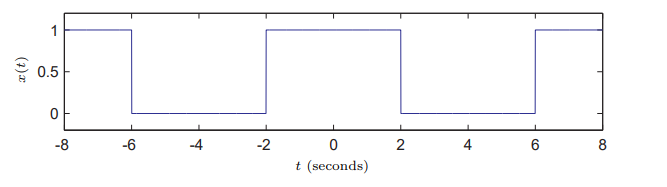

Here it is immediately apparent that the period is T = 8 seconds (track any point and see when next it is repeated). Thus $\omega_0 = \frac{2\pi}{T} = \frac{2\pi}{8} = \frac{\pi}{4} $ . Choosing an integration interval of [-T/2, T/2] allows us to capure all the details of x(t) for our definition of the Fourier coefficients.

Note the DC component $a_0
$ will often need to be evaluated on its own, as the general function of k that results from the integral may be undefined at k = 0. Solving for this DC component yields:


$$\[
a_0 = \frac{1}{T} \int_{-T/2}^{T/2} e^{-j 0 \cdot (\omega_0) t} \, dt
 = \frac{1}{8} \int_{-4}^{4} e^{-j 0 \cdot (\pi/4) t} \, dt
 = \frac{1}{8} \int_{-2}^{2} e^{-j 0 \cdot (\pi/4) t} \, dt
= \frac{1}{8} \int_{-2}^{2} 1 \, dt
= \frac{1}{8} \cdot 4
= \frac{1}{2}
\]
$$


Thus we may now evaluate the rest of the coefficients:

a0 = 0.5;
syms Ts w0 t k

f = exp(-j*k*w0*t);

%integrate over a subset of [-T/2, T/2] where x is non-zero, here [-2, 2]
%and in this interval x = 1:
ak_sym = 1/Ts *int(f, t, -2, 2);
ak_sub = subs(ak_sym, [Ts, w0], [8, pi/4]) %Plug in T and w0

$$ak\_sub = \frac{\sin\left(\frac{\pi \,k}{2}\right)}{k\,\pi }$$

Which is in keeping with evaluating the integral by hand (check for yourself).

Now all we need to do is fill in the vector a_k for each k. Let's discretize k and choose k between -10 and 10. 

k_vals = -8:8;
ak = zeros(1, length(k_vals));

for idx = 1:length(k_vals)
    k_val = k_vals(idx); 
    %manually set a0
    if k_val == 0 
        ak(idx) = a0;
    else
        ak(idx) = double(subs(ak_sub, k, k_val));
    end
end
ak

ak =          0   -0.0455         0    0.0637         0   -0.1061         0    0.3183    0.5000    0.3183         0   -0.1061         0    0.0637         0   -0.0455         0


Now we may extract the magnitude and phase from the complex vector ak:

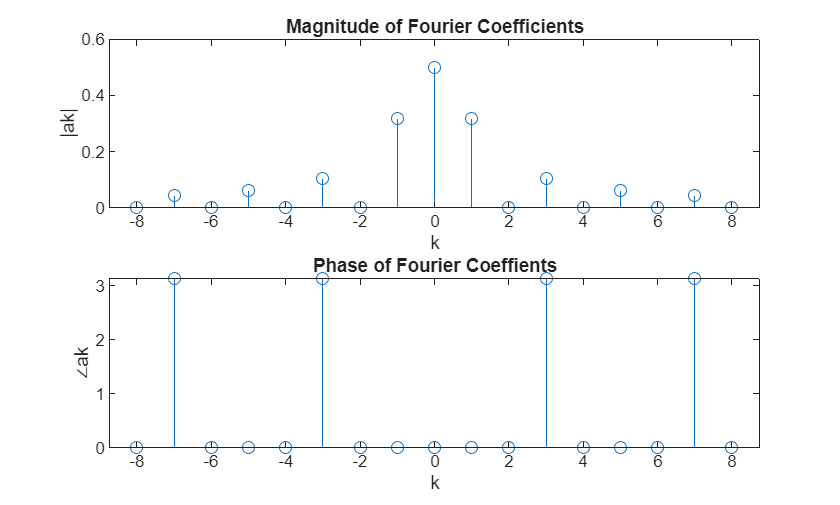

ak_mag = abs(ak);
ak_phase = angle(ak);

figure;
subplot(2,1,1);
stem(k_vals, ak_mag);
title("Magnitude of Fourier Coefficients")
xlabel('k')
ylabel('|ak|')

subplot(2,1,2);
stem(k_vals, ak_phase);
title("Phase of Fourier Coeffients")
xlabel('k');
ylabel('∠ak')

Easy peasy right? Let's see how this reconstruction compares to our true signal.

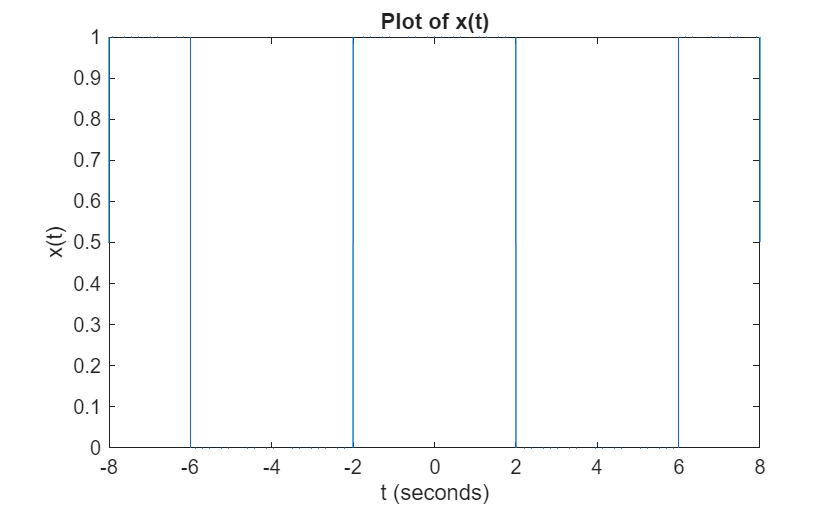


t = -8:0.001:8;
x_actual = heaviside(t+8) - heaviside(t+6) + heaviside(t+2) - heaviside(t-2) + heaviside(t-6) - heaviside(t-8);
x_actual = double(x_actual);
figure
plot(t,x_actual)
title("Plot of x(t)")
xlabel("t (seconds)")
ylabel("x(t)")

Now for the reconstruction:

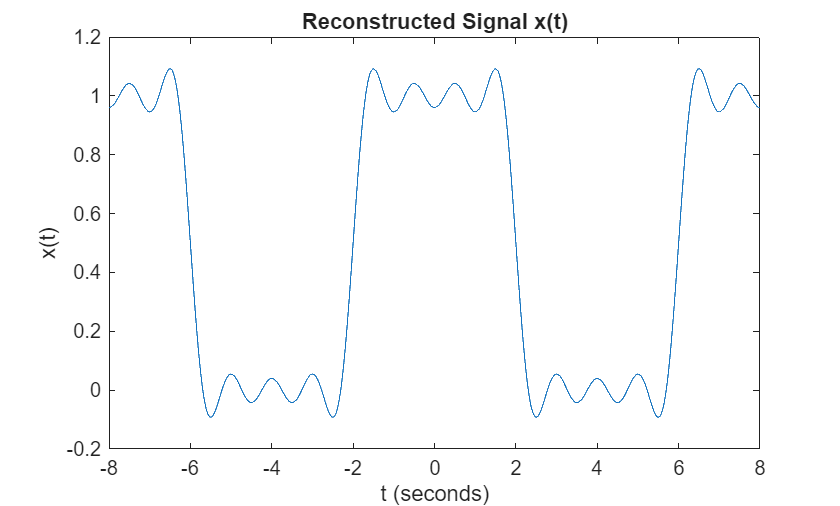

x_reconstruct = zeros(size(t));
Ts = 8;
for idx = 1:length(k_vals)
    x_reconstruct = x_reconstruct + (ak(idx) * exp(1j * k_vals(idx) *2*pi/Ts *t));
end
x_reconstruct = real(x_reconstruct);
figure;
plot(t, x_reconstruct);
title("Reconstructed Signal x(t)");
xlabel("t (seconds)");
ylabel("x(t)");

We can increase the accuracy of the reconstruction by increasing the number of Fourier coefficients (increase k_vals).

Below is a script I wrote to help you visualize how the signal approaches the original as the coefficient count increases. Do not use this method for any of your handin questions.

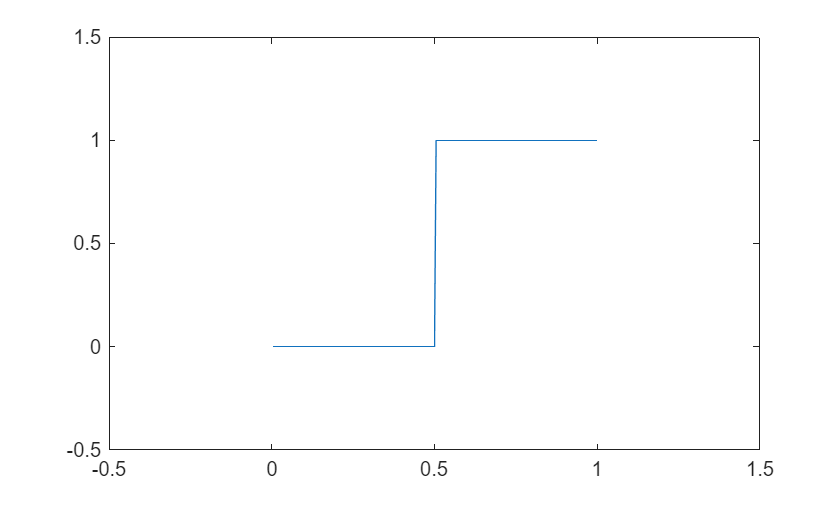

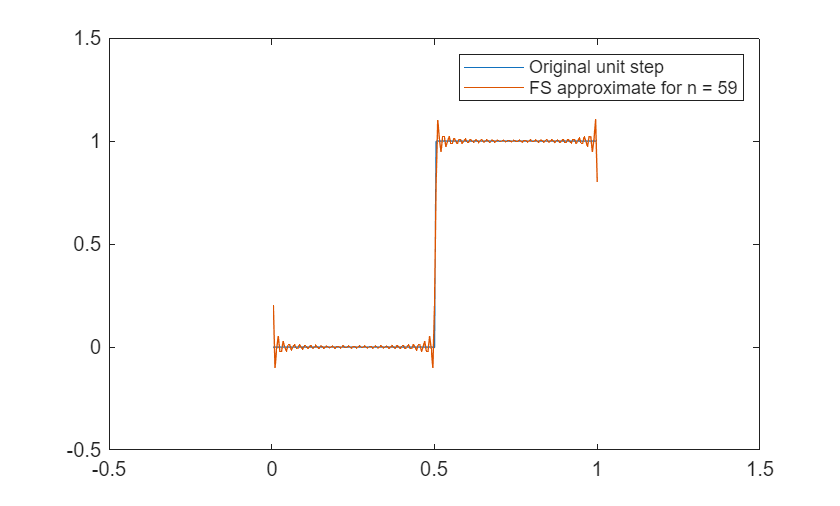

%Running this code will show an animation.
%The following will be an attempt to represent various
%Functions using the Fourier series

clc, clf;
clear all, close all;

dx = 0.005;
L = 1;
x = dx:dx:L; %starts at approx 0 but not
%Another reason is because length is now 200 not 201
%And there would be double counting
f = ones(size(x));
%turn f from 1 from 0to L to be 0 from 0 to L/2 then 1 from L/2 to L
f(1:length(f)/2) = 0*f(1:length(f)/2);
plot(x,f)
%note could comment away lines 14 and 15 and replace with:
%f = sin(@*pi*x)
axis([-0.5, 1.5, -0.5, 1.5])
hold on

%Now for FS approximations:
fFS = zeros(size(x));
%DC offset
A0 = (2/L)*sum(f.*ones(size(x)))*dx;
%The 'm' stuff is for visual of seeing how u increase n the approx gets
%better
for m = 1:100 
    hold off
    plot(x,f)
    axis([-0.5, 1.5, -0.5, 1.5])
    
    %Initially starting at n = 0:
    fFS = A0/2;
    
    %Now for the series rep:
    
    for n = 1:m
        An = (2/L)*sum(f.*cos(2*pi*n*x/L))*dx;
        Bn = (2/L)*sum(f.*sin(2*pi*n*x/L))*dx;
        
        fFS = fFS + An*cos(2*pi*n*x/L) + Bn*sin(2*pi*n*x/L);    
    end
    hold on
    plot(x,fFS)
    legend("Original unit step", "FS approximate for n = " + m)

    drawnow
    pause(0.01)
end


%Note at m(n) = 100, we get an exact replica. This is due to aliasing due
%to the specific dx = 0.005 and L = 1 (ie 200 pts)

## Section 2: Fourier Transform

Recall the Fourier Transform analysis equation:


$$$X(\omega) = \int_{-\infty}^{\infty} x(t) e^{-j \omega t} \, dt$
$$


and the Fourier Transform synthesis equation:


$$$x(t) = \frac{1}{2\pi} \int_{-\infty}^{\infty} X(\omega) e^{j \omega t} \, d\omega$
$$


To find the Fourier transform in MATLAB is simple enough. For example let x(t) = p(t). Then:

syms t w

% Define the signal x(t)
x = heaviside(t + 0.5) - heaviside(t - 0.5);

% Define the Fourier transform
X = int(x*exp(-1j*w*t), t, -0.5, 0.5);  %If you use -Inf to Inf it will be correct but the output won't be familiar

% Simplify the result
X = simplify(X)

$$X = \frac{2\,\sin\left(\frac{w}{2}\right)}{w}$$

Which is == to sinc(w/2pi) as expected. The real problem is inverse Fourier transforming as we often need the full -Inf to Inf integration limits, which symbolically will output something unrecognizable. Instead we can use numerical methods and plot our solutions:

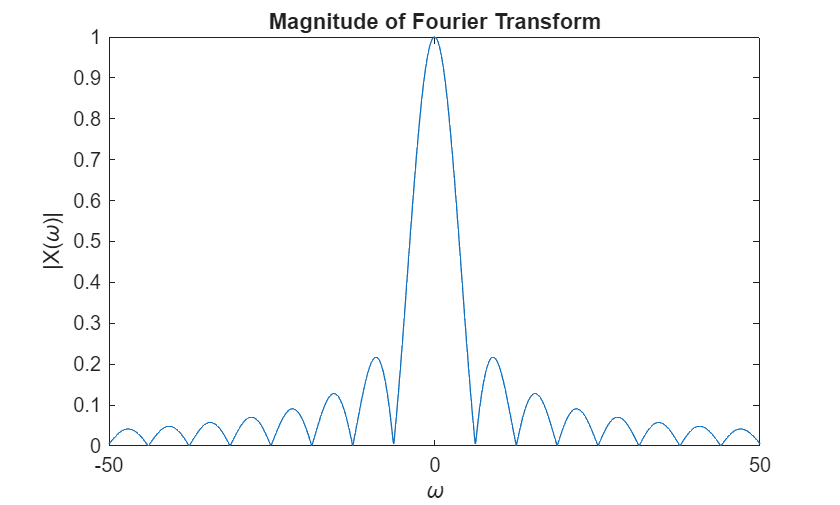

t = -10:0.01:10;
x = double(heaviside(t + 0.5) - heaviside(t - 0.5)); %define x(t)

w = linspace(-50, 50, 1000); %Create an arb frequency range
X = zeros(1, length(w));

for idx = 1:length(w)
    X(idx) = trapz(t, x.*exp(1j*w(idx)*t)); %Fill X using the analysis equation
end

figure;
plot(w, abs(X));
xlabel('\omega'); ylabel('|X(\omega)|');
title('Magnitude of Fourier Transform');

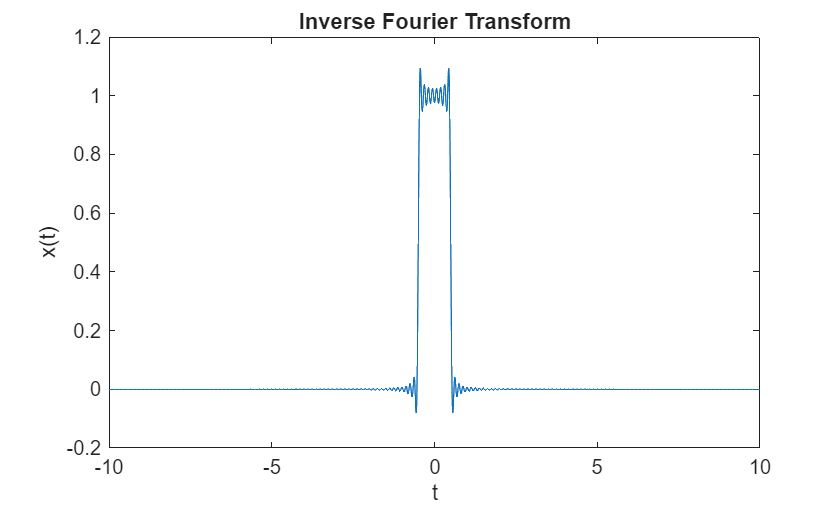

%And to inverse transform:
x_reconstruct = zeros(1, length(t));
for idx = 1:length(t)
    x_reconstruct(idx) = (1/(2*pi))*trapz(w, X.*exp(1j*w*t(idx)));
end

figure;
plot(t,real(x_reconstruct));
xlabel('t'); ylabel('x(t)');
title('Inverse Fourier Transform');

### Utilizing built in Fourier Transform functions in MATLAB

Computing the Fourier transform is often laborious and numerically inaccurate. An excellent built in Fourier transform function provided by MATLAB is their implementation of the Fast-Fourier-Transform algorithm (fft). This is an algorithm that speeds up the usual discrete Fourier transform algorithm. Consider a set of data points $[f_0, f_1, f_2 ... ,f_{N-1}]
$' (where ' denotes transpose), we want to rewrite this vector as a sum of sinusoids, in particular we wish to calculate the amplitude of each frequency $[\hat f_0, \hat f_1 , \hat f_2 , ..., \hat f_{N-1}]$'. To do this, we clearly need to create a matrix which we will multiply the data points by to attain the frequency amplitudes (rather the amplitudes of each sinusoid comprising the signal).

For starters, let $\omega_n = e^{-j2\pi/N}$. Now the full DFT matrix F is thus:


$$F_N = \left[ 
\begin{array}{cccc}
1 & 1 & \cdots & 1 \\
1 & \omega_N & \cdots & \omega_N^{N-1} \\
\vdots & \vdots & \ddots & \vdots \\
1 & \omega_N^{N-1} & \cdots & \omega_N^{(N-1)(N-1)}
\end{array}
\right]
$$
 

And thus we have the following relationship:


$$\hat{f}_{k} = (F^{} f)_{k}
$$


A problem with this algorithm is that it is of order $\Theta(n^{2})
$ which means that doubling the length of data quadruples the computation time. A faster algorithm was devised called the Fast Fourier Transform. An interesting fact about the FFT is that it was utilized to detect underground nuclear testing by analzing seismic activity to differentiate between earthquakes and explosions. Previously nuclear testing was banned on land, space and underwater, but not underground because no one could detect it!

The FFT has order $\Theta(nlog(n)
)
$. The trick to utilizing the algorithmic efficiency of the FFT if N (the number of samples/data points) is a power of 2. Let's consider 1024 data points, and define the matrix $F_{1024}$ as a mapping from the data set {x} to the Fourier coefficients $\{\hat x\}$. Thus we have $\hat x = F_{1024}x$. We can then break this down as follows:


$$\hat{x} =
\left[
\begin{array}{cc}
I & -D \\
I & -D
\end{array}
\right]
\left[
\begin{array}{cc}
F_{512} & 0 \\
0 & F_{512}
\end{array}
\right]
\left[
\begin{array}{c}
x_{\text{even}} \\
x_{\text{odd}}
\end{array}
\right]
$$


Where I is the identity matrix and D is an 'easy' to compute diagonal matrix (as most entries are zero):


$$D = \mathrm{diag}\!\left( 1,\; \omega_{N},\; \omega_{N}^{2},\; \ldots,\; \omega_{N}^{(N/2-1)} \right),
\qquad \omega_{N} = e^{-j 2\pi / N}
$$


And of course in our example N = 1024. Notice that we basically extract the even and odd samples entries and then stack them in the RHS vector, and then reshuffle them around with the LHS matrix. 

Notice that we can just keep splitting up our F matrix, because it has a power of 2 number of entries! Even if N is NOT a power of 2, just pad it with zeros until it is!

### FFT in MATLAB

To use the fft in MATLAB is very simple because it is a built in function. It taken in 2 inputs, a data set 'x' and the number of samples N (N is equal to the length of x):

dt = 0.001;
t = 0:dt:1;
x = sin(2*pi*50*t) + sin(2*pi*120*t);
N = length(x);
X = fft(x,N);

Where X holds the Fourier coefficients of the signal. To calculate the power in each frequency, compute the power spectral density (PSD):

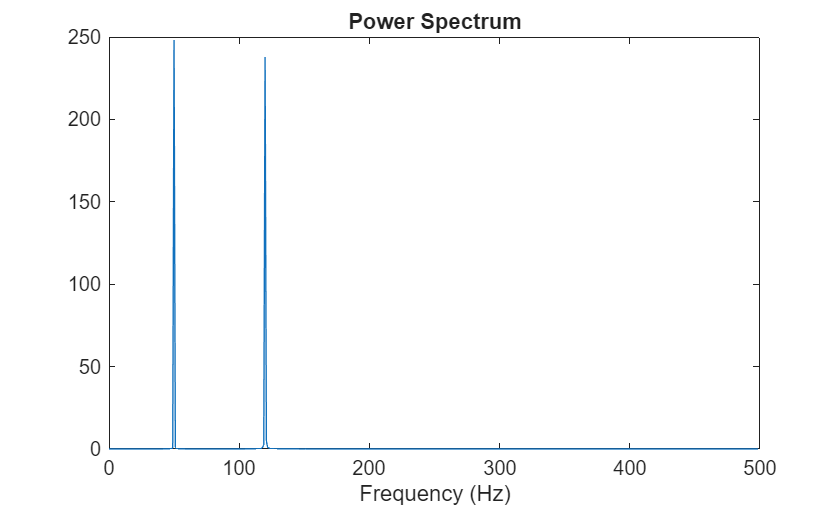

PSD = X.*conj(X)/N; %PSD = *X times X conjugate) normalized
freq = 1/(dt*N)*(0:N); %Think about how and why this vector is structured as so
L = 1:floor(N/2); %Only plot first half of frequencies
figure
plot(freq(L), PSD(L));
title("Power Spectrum");
xlabel("Frequency (Hz)");

This allows us to identify the dominant frequencies in the signal. Of course for this signal it is f = 50Hz and f = 120Hz.

## Section 3: Questions

### Question 1: Frequency domain representation of Fourier Series

For the given signal below:

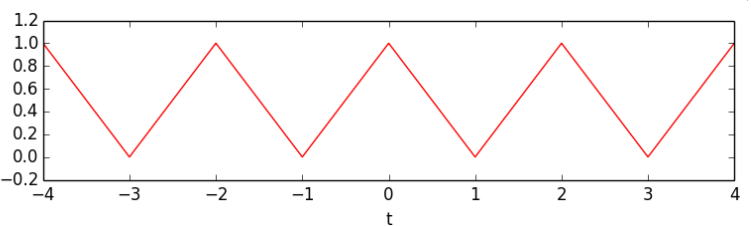

Firstly, using the method described in this handout calculate the MAGNITUDES of the Fourier Coefficients. Store these in a vector titled **ak_mag**. Then by hand provide a closed form expression for these coefficients, and store their PHASE in a vector titled **ak_phase. **Provide a plot of both of these in the same form as shown in these notes (copy paste).

### Question 2: Signal reconstruction with Fourier Series

Find and plot using symbolic processing and the method described in this document Fourier series reconstruction of x(t) defined by:

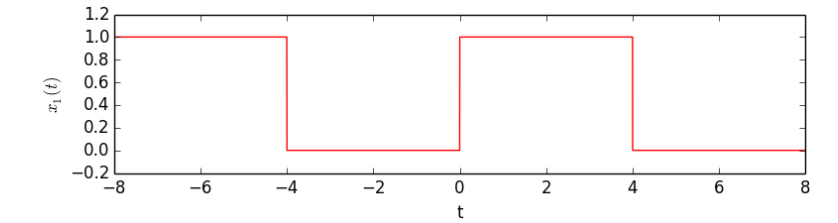

Note how this is similar but not precisely the same as the example in this document. Can you spot the relationship between them? Plot the signal above as well as its reconstruction for t between -8 and 8 in increments of 0.001 and find the Fourier Coefficients of this new signal by relating them to the example. Store the original signal in a variable called **x_actual** and the reconstructed signal in a variable called **x_reconstruct**. Store the Fourier Coefficients of the reconstructed signal in a variable called **dk **and the Fourier Coefficients of the signal you are relating to **x_actual** in a variable called **ak. **

### Question 3: Fourier Transform comparison

Recall that convolution in time is multiplication in the frequency domain. Use this property to find the Fourier series representation of x(t) defined below (has amplitude = 1):

Convolve a rectangle function with a delta train to acquire the above signal, and find the Fourier transform of this. Then manipulate this expression and then inverse Fourier transform back to the time domain. From this, your answer should be in a form similar to that of a Fourier series representation of x(t). Store the coeffients in a vector called Ck. 

Compare your solution by performing the usual integration for the coefficients, ie no Fourier transform used. Store this value in Ck_int.

%SOMEHOW GET THEM TO USE MY FT CODE

### Question 4: Low pass filter using the FFT

Part 1:

Consider the example of FFT usage discussed in this document. For x(t) defined as:


$$x(t) = sin(100\pi t) + sin(240\pi t)$$


For t between 0 and 1, with dt = 0.001. Create a noisy version of this signal by adding zero mean, unit standard deviation noise scaled by 2.5, and store this in a variable titled 'y'. Plot both of these signals on the same axes, x in blue and y in red and add an appropriate legend. 

Part 2:

Find the power spectral density of the noisy signal using the method discussed in this document. Remember to define your frequency axis correctly. Next, create a low pass filter that will zero all PSD elements with power less than 50. Plot both PSD's on the same set of axes with an appropriate legend.

Part 3:

Perform an inverse fourier transform using ifft to extract the time domain rendition of the filtered signal. Remember that you need to zero all elements of Y that have power < 50. Plot y and y_filtered on the same axes with an appropriate legend. 

Finally, run the built in 'sound' function to hear your solution! The code is provided, so whenever you run your code either section break each sound or comment them all but one out to hear what the signal sounds like. Your answer is correct if x doesnt sound like y, but x sounds like y_filtered!

### Question 5: 2D FFT for image compression

In this question you will apply a 2-D FFT to compress an image by keeping only the biggest Fourier coefficients. Work with the provided DrPhil.jpg file.

Part 1:

- Load the image using **imread.**

- Convert it to grayscale using **rgb2gray.**

- Store the grayscaled image in a variable titled **A.**

- Store the x and y dimensions of the image in variables **nx **and **ny**.

Part 2:

- Compute the 2D FFT of the image using **fft2.**

- Store this result in a variable called **Ahat.**

Part 3:

- Compute **maxAbs = max(abs(Ahat(:)));**

- Create the following three threshold values **thresh_list = 0.8 * [0.001 0.005 0.01] * maxAbs;**

- For each threshold **thresh**, create a binary mask: **mask = abs(Ahat) > thresh;**

- Apply the mask to ensure only large coefficients: **Ahat_low = Ahat.*mask;**

- Compute the ifft using **ifft2.**

- Convert to an unsigned 8-bit image using **uint8.**

Part 4:

Create a 2x2 subplot figure:

- Top left = A

- Top right = threshlist(1)

- Bottom left =  threshlist(2)

- Bottom right = threshlist(3)

Each plot must be titled **% of FFT basis **where the % is given by **percent_kept = 100 * nnz(mask) / numel(mask);**